% Define las ecuaciones diferenciales
syms x y
% Exercise 2-2
fx = x*(3-2*x-y)

$$fx = -x\,\left(2\,x+y-3\right)$$

fy = y*(2-x-y)

$$fy = -y\,\left(x+y-2\right)$$

% setting the matlab function for our system
f_lmb = @(t,z) [z(1)*(3 - 2*z(1) - z(2)); z(2)*(2 - z(1) - z(2))];

% 1. CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y])

fixPts = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]


fixPts = double([fixPts.x'; fixPts.y'])

fixPts =          0         0    1.0000    1.5000
         0    2.0000    1.0000         0



% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts, 2));

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% 2. IDENTIFY IF THE FIXED POINTS ARE HYPERBOLIC
% 3. CLASSIFICATION OF THE FIXED POINTS
for k =1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) == 0)
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (0.000000, 0.000000) is not hyperbolic.
Fixed point at (0.000000, 2.000000) is not hyperbolic.
Fixed point at (1.000000, 1.000000) is not hyperbolic.
Fixed point at (1.500000, 0.000000) is not hyperbolic.



% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');


% 4. COMPUTE THE NULLCLINES
xcline_x = solve(fx == 0, x);
ycline_y = solve(fy == 0, y);

% Representing the nullclines
nullX = fimplicit(fx, [-eps 3.5 -eps 2.5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-eps 3.5 -eps 2.5], 'g--', 'LineWidth', 1.5);

% 6. REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(0, 4, N);
ylin = linspace(0, 2.5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);
% Computing the grid
fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing the flow of the system with quiver
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

axis([-eps 3.5 -eps 2.5]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

% 7. DRAW THE PHASE PORTRAIT
% 5. REPRESENT A TRAJECTORY 
% Initialise at (1, 0.5)
y0 =[1 0.5];
t0 = 0.5; tf = 30;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% Initialise at (0.5, 2)
y0 =[0.5 2];
t0 = 0.5; tf = 30;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% 8. REPRESENT THE BASINS OF ATTRACTION IN THE PHASE DIAGRAM
% 9. PAINT A TRAJECTORY FOR EACH BASIN
% As there are no saddles, we will print the basins of the stable node (all in reverse time)
t0 = 0.5; tf = 30;
tspam = [tf,t0];

eps = 0.1

eps = 0.1000

y1 = (eigenvectors(:, 1, 3)*eps)+fixPts(:,3)

y1 =     0.9149
    0.9474


[ts,ys] = ode45(f_lmb,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = -(eigenvectors(:, 1, 3)*eps)+fixPts(:,3)

y2 =     1.0851
    1.0526


[ts,ys] = ode45(f_lmb,tspam, y2);

basin2 = plot(ys(:,1),ys(:,2),'black-');

y3 = (eigenvectors(:, 2, 3)*eps)+fixPts(:,3)

y3 =     1.0526
    0.9149


[ts,ys] = ode45(f_lmb,tspam, y3);

basin3 = plot(ys(:,1),ys(:,2),'black-');

y4 = -(eigenvectors(:, 2, 3)*eps)+fixPts(:,3)

y4 =     0.9474
    1.0851


[ts,ys] = ode45(f_lmb,tspam, y4);

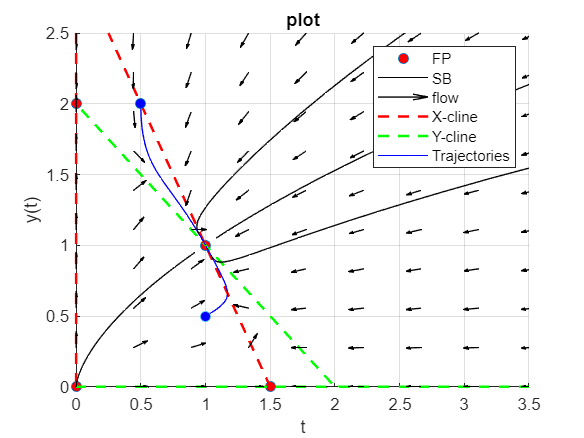

basin4 = plot(ys(:,1),ys(:,2),'black-');
xlabel('t');ylabel('y(t)');grid on; title('plot')

legend([fpts basin1 flow nullX nullY traj1], ...
    {'FP', 'SB', 'flow', 'X-cline', 'Y-cline', 'Trajectories'}, ...
    'Location', 'NorthEast')


disp(['The middle fixed point is a stable node, having two saddles and one unstable node.' ...
    'Thus, no matter the initial condition, the populations will balance always.'])

The middle fixed point is a stable node, having two saddles and one unstable node.Thus, no matter the initial condition, the populations will balance always.
